# **README**

**请先运行训练文件后再运行测试文件，期间不要清空工作区。**

**Please run the training file before the test file, without emptying the workspace.**

if isfolder('D:\Work Files\MATLAB\labW3_codes\IMU') %👈change this to your location
    addpath(genpath('D:\Work Files\MATLAB\labW3_codes\IMU'))
    disp('You are in the correct directory. Please continue.')
else  
    disp('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## 导入数据（和训练文件一样）Importing data (same as training files)

testData = readtable('test.csv');

back_x = testData.Feature_1;
back_y = testData.Feature_2;
back_z = testData.Feature_3;
thigh_x = testData.Feature_4;
thigh_y = testData.Feature_5;
thigh_z = testData.Feature_6; 
Activitytest = testData.Activity;

backX_mean = mean(back_x, 2);
backY_mean = mean(back_y, 2);
backZ_mean = mean(back_z, 2);
thighX_mean = mean(thigh_x, 2);
thighY_mean = mean(thigh_y, 2);
thighZ_mean = mean(thigh_z, 2);

backX_std = std(back_x, [], 2);
backY_std = std(back_y, [], 2);
backZ_std = std(back_z, [], 2);
thighX_std = std(thigh_x, [], 2);
thighY_std = std(thigh_y, [], 2);
thighZ_std = std(thigh_z, [], 2);

ActivityDataTest = [backX_mean backY_mean backZ_mean backX_std backY_std backZ_std ...
    thighX_mean thighY_mean thighZ_mean thighX_std thighY_std thighZ_std];

clear backX_mean backY_mean backZ_mean backX_std backY_std backZ_std thighX_mean thighY_mean thighZ_mean thighX_std thighY_std thighZ_std;

# **!!**

**先用APP里的分类学习器来完成训练部分，训练完成后导出trainmodel再进行。**

**Please use the ****classification learner ****in the APP to complete the training part first, and export ****trainModel ****after the training is completed. ( Use holdout method in 10%, because the dataset is too large)**

% Use the model to make predictions
[acts, scores] = trainedModel.predictFcn(ActivityDataTest)

acts =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


scores =     0.6685    0.0448    0.0819    0.0416    0.0285    0.0481    0.0014    0.0001    0.0735    0.0061    0.0031    0.0026
    0.6685    0.0448    0.0819    0.0416    0.0285    0.0481    0.0014    0.0001    0.0735    0.0061    0.0031    0.0026
    0.6724    0.0408    0.0672    0.0320    0.0469    0.0659    0.0359    0.0009    0.0329    0.0033    0.0008    0.0011
    0.6724    0.0408    0.0672    0.0320    0.0469    0.0659    0.0359    0.0009    0.0329    0.0033    0.0008    0.0011
    0.6724    0.0408    0.0672    0.0320    0.0469    0.0659    0.0359    0.0009    0.0329    0.0033    0.0008    0.0011
    0.6724    0.0408    0.0672    0.0320    0.0469    0.0659    0.0359    0.0009    0.0329    0.0033    0.0008    0.0011
    0.6724    0.0408    0.0672    0.0320    0.0469    0.0659    0.0359    0.0009    0.0329    0.0033    0.0008    0.0011
    0.6724    0.0408    0.0672    0.0320    0.0469    0.0659    0.0359    0.0009    0.0329    0.0033    0.0008    0.0011
    0.6724    0.0408   


% Save the prediction results as a CSV file
writetable(table(acts), 'predictedResults.csv');

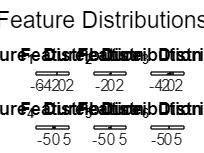

figure;
feature_columns = {'Feature_1', 'Feature_2', 'Feature_3', 'Feature_4', 'Feature_5', 'Feature_6'};
for i = 1:length(feature_columns)
    subplot(2, 3, i); 
    histogram(testData.(feature_columns{i}), 'FaceColor', rand(1, 3));
    title([feature_columns{i} ' Distribution']);
end
sgtitle('Feature Distributions');

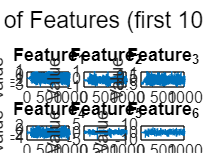


figure;
for i = 1:length(feature_columns)
    subplot(2, 3, i); 
    plot(testData.(feature_columns{i}) (1:1000)); % Take the first 1000
    title(feature_columns{i});
    ylabel('Value');
end
sgtitle('Time Series of Features (first 1000 samples)');